detectBout();

reduceTailDim();

dtw_alignBout();

[idx_apcluster,idx_kmeans,idx_spectral,sil_apcluster,sil_kmeans,sil_spectral] = embedBout2Cluster();

find the exemplar of each cluster, or is the bout really similar to each other under one cluster

[sessionID,fishID] = getfish();
numBout_per_fish = zeros(length(sessionID),1);
for i=1:length(sessionID)
   load(fullfile(getpath('behavior',sessionID{i},fishID{i}),'tail_swing'),'bout_idx') ;
   numBout_per_fish(i) = length(bout_idx);
end
save(fullfile(getpath('result'),'tail_pca'),"numBout_per_fish",'-append');

fishID_bout = arrayfun(@(i) i*ones(numBout_per_fish(i),1),1:8,'un',0);
fishID_bout = cat(1,fishID_bout{:});

%exemplar of each cluster to investigate whether the cluster is
%interpretable or not
load(fullfile(getpath('result'),'tail_pca'),'bout_all','score','coeff','latent','single_bout_len');
idx = idx_kmeans;
C = unique(idx);
numC = length(C);
dist = zeros(numC,1);
exemplar = cell(numC,1);
for i=1:numC
    mask = find(idx==C(i));
    bout_cluster = arrayfun(@(i) score(sum(single_bout_len(1:mask(i)-1))+1:sum(single_bout_len(1:mask(i))),1:3),1:length(mask),'un',0);
    %stretch bouts with different length into an exemplar by strech
    %one-pair-by-one-pair
    dist_tmp_pos = arrayfun(@(i) ...
        arrayfun(@(j) dtw(bout_cluster{i}',bout_cluster{j}'),(i+1:length(bout_cluster))'),...
        (1:length(bout_cluster))','un',0);
    dist_tmp_neg = arrayfun(@(i) ...
        arrayfun(@(j) dtw(bout_cluster{i}',-bout_cluster{j}'),(i+1:length(bout_cluster))'),...
        (1:length(bout_cluster))','un',0);
    dist_tmp_pos = squareform(cat(1,dist_tmp_pos{:}));
    dist_tmp_neg = squareform(cat(1,dist_tmp_neg{:}));
    dist_tmp = min(cat(3,dist_tmp_pos,dist_tmp_neg),[],3);
    [dist(i),I] = min(mean(dist_tmp));
    exemplar{i} = bout_cluster{I};
end
exemplar = cellfun(@(x) x*coeff(:,1:3)'+mean(bout_all,1),exemplar,'UniformOutput',false);
% figure,[row,col] = arrange_subplots(numC);
% for i=1:numC
%     subplot(row,col,i),hold on;
%     arrayfun(@(j) plot(exemplar{i}(j,:)'+j-1,'Color','k'),1:size(exemplar{i},1),'un',0);
%     title(['cluster ' num2str(i)]);
%     xlabel('tail segment');ylabel('time');
% end

find outlier bouts

idx_outlier = find(single_bout_len<10);
[row,col] = arrange_subplots(length(idx_outlier));
figure,
for i=1:length(idx_outlier)
    [whichfish,whichbout] = findbout_pool2single(idx_outlier(i));
    load(fullfile(getpath('behavior',sessionID{whichfish},fishID{whichfish}),'tail_swing'),'sum_curv','bout_idx');
    subplot(row,col,i)
    plot(sum_curv(bout_idx(whichbout,1)-20:bout_idx(whichbout,2)+20));
end

Is DTW right?

load(fullfile(getpath('results'),'tail_boutdist'),'boutdist');
k = 10;
mask = tril(true(size(boutdist,1)),-1);
pair_boutdist = boutdist(mask);
[~,idxMin] = mink(pair_boutdist,k);
[~,idxMax] = maxk(pair_boutdist,k);
idx = nchoosek(1:size(boutdist,1),2);
idx = [idx(:,2),idx(:,1)];
far_bout_pair = idx(idxMax,:);%k x 2
near_bout_pair = idx(idxMin,:);
load(fullfile(getpath('result'),'tail_pca.mat'),'bout_all');
bout_all_tmp = arrayfun(@(i) bout_all((sum(single_bout_len(1:i-1))+1):sum(single_bout_len(1:i)),:),(1:length(single_bout_len))','un',0);
for i=1:k
    figure,
    subplot(2,2,1)
    plot(bout_all_tmp{far_bout_pair(i,1)}'+(1:size(bout_all_tmp{far_bout_pair(i,1)},1)),'Color','k');
    title(num2str(far_bout_pair(i,1)));
    subplot(2,2,2)
    plot(bout_all_tmp{far_bout_pair(i,2)}'+(1:size(bout_all_tmp{far_bout_pair(i,2)},1)),'Color','k');
    title(num2str(far_bout_pair(i,2)));
    subplot(2,2,3)
    plot(bout_all_tmp{near_bout_pair(i,1)}'+(1:size(bout_all_tmp{near_bout_pair(i,1)},1)),'Color','k');
    title(num2str(near_bout_pair(i,1)));
    subplot(2,2,4)
    plot(bout_all_tmp{near_bout_pair(i,2)}'+(1:size(bout_all_tmp{near_bout_pair(i,2)},1)),'Color','k');
    title(num2str(near_bout_pair(i,2)));
end

boutsim = exp(-boutdist.^2);
thld = quantile(boutsim,.999,'all');
boutsim(boutsim<thld) = 0;
boutsim = tril(boutsim,-1);
g = graph(boutsim,'lower');
idx_conncomp = conncomp(g);
figure,
LWidth = 2*g.Edges.Weight/max(g.Edges.Weight);
h = plot(g,'NodeLabel',{},'NodeCData',color,'NodeColor','flat','Layout',"force",'UseGravity',true);
title('force layout');
figure,
h = plot(g,'NodeLabel',{},'Layout',"subspace",'Dimension',size(boutdist,1));
title('subspace layout');

some bouts are distant from all other bouts, so they are possibly outliers. Let's delete those bouts and see if the remaining bouts are distant from each other in some pattern.

m_boutdist = mean(boutdist,1);
idx_del = m_boutdist > quantile(m_boutdist,.7);
boutdist_new= boutdist;
boutdist_new(idx_del,:) = [];
boutdist_new(:,idx_del) = [];
figure,
imagesc(boutdist_new)

Check if one fish's bouts are nearer to itself than to others

bout_startIdx_fish = cumsum(numBout_per_fish);
boutdist_fish = zeros(length(fishID));
for i=1:length(fishID)
    for j=1:length(fishID)
        boutdist_fish(i,j) = median(boutdist((sum(numBout_per_fish(1:i-1))+1):sum(numBout_per_fish(1:i)),...
            (sum(numBout_per_fish(1:j-1))+1):sum(numBout_per_fish(1:j))),'all');
    end
end

check fish 0705 and 0717 behavior

focus_fish = 5;
idx_perm = randperm(numBout_per_fish(focus_fish),2);
idx_perm = sum(numBout_per_fish(1:focus_fish-1)) + idx_perm';
bouts_perm = arrayfun(@(i) bout_all(sum(single_bout_len(1:idx_perm(i)-1))+(1:single_bout_len(idx_perm(i))),:),1:length(idx_perm),'un',0);
figure,
subplot(1,2,1),
plot_continuous_bouts(gca,bouts_perm{1});
subplot(1,2,2),
plot_continuous_bouts(gca,bouts_perm{2});
sgtitle(boutdist(idx_perm(1),idx_perm(2)));

check the bout length distribution of different fish

fish_bout_len = zeros(8,1);
figure,hold on
for i=1:length(fishID)
    idxtmp = (sum(numBout_per_fish(1:i-1))+1):sum(numBout_per_fish(1:i));
    subplot(2,4,i)
    histogram(single_bout_len(idxtmp),'BinWidth',1,'Normalization','probability');
    ax=  gca;
    ax.XLim = [0 80];
    legend(sessionID{i});
    fish_bout_len(i) = mean(single_bout_len(idxtmp));
end

check if the difference of bout length correlates to bout distance

bout_len_diff = zeros(size(boutdist,1));
for i=1:numBout
    for j=i+1:numBout
        bout_len_diff(i,j) = abs(single_bout_len(i)-single_bout_len(j));
    end
end
bout_len_diff = bout_len_diff + bout_len_diff';
figure,
scatter(bout_len_diff(:),boutdist(:),10,'filled');

figure,
focus_bout = [1 6 7 38 40 42];
numFigure = length(focus_bout);
[row,col] = arrange_subplots(numFigure);
for i=1:numFigure
    subplot(row,col,i),plot_continuous_bouts(gca,bout_all_tmp{focus_bout(i)});  
end
boutdist(focus_bout,focus_bout)

load(fullfile(getpath('result'),'tail_cluster'),'idx_apcluster','idx_kmeans','idx_spectral');

check if original apcluster method gives better result, delete the clusters with too few samples and corresponding bouts, check if the remaining clusters are meaningful or not.

[idx_apcluster,netsim,~,unconverged,dpsim,expref] = apcluster(-boutdist,-median(boutdist(:)),'convits',nconv,'maxits',nrun,'dampfact',lam,'noplot');
[cluster,ia,ic] = unique(idx_apcluster);
numC = zeros(length(cluster),1);
for i=1:length(cluster)
    numC(i) = nnz(idx_apcluster==cluster(i));
end
cluster_del = cluster(numC<=3);
mask = ismember(idx_apcluster,cluster_del);
idx_apcluster_rem = idx_apcluster;
idx_apcluster_rem(mask) = [];

here we get 104 microclusters, and for each microcluster, we examine their expref, and also if the bouts in one cluster is really similar

cluster = unique(idx_apcluster_rem);
exemplar = zeros(length(cluster),1);
sz_cluster = zeros(length(cluster),1);
for i=1:length(cluster)
    idx_per_cluster=find(idx_apcluster_rem==cluster(i));
    sz_cluster(i) = length(idx_per_cluster);
    boutsim_tmp = -boutdist(idx_per_cluster,idx_per_cluster);
    [~,I] = max(mean(boutsim_tmp,1));
    exemplar(i) = idx_per_cluster(I);
end

boutdist(mask,:) = [];boutdist(:,mask) = [];

boutdist_microcluster = boutdist(exemplar,exemplar);
[mappedX,mapping] = drtoolbox.techniques.isomap(boutdist_microcluster,2,12);
figure,
plot_exemplar_click(mappedX,sz_cluster,bout_all_tmp(exemplar));
colormap('jet')

hierarchical clustering and see if seven cluster could give a satisfying result

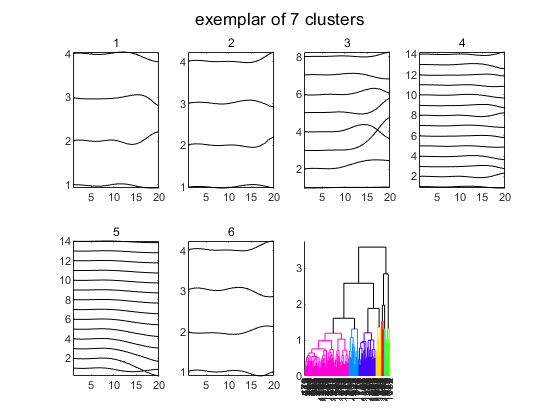

z = linkage(boutdist_microcluster,'complete');
T = cluster(z,'maxclust',7);
cutoff = median(z(end-7:end-3,3));
[~,T2] = dendrogram(z,length(exemplar),'ColorThreshold',cutoff,'Labels',cellfun(@num2str,num2cell(exemplar),'un',0));
set(gca,'XTickLabelRotation',90);

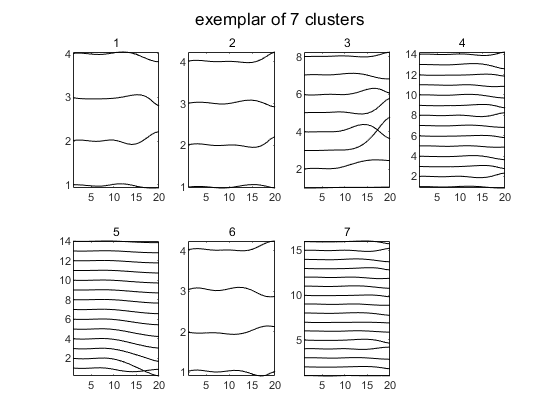

C = unique(T);
final_exemplar = zeros(length(C),1);
sz_finalCluster = final_exemplar;
idx_apcluster_final = zeros(length(idx_apcluster_rem),1);
figure,
[row,col] = arrange_subplots(length(C));
for i=1:length(C)
    idxtmp = find(T==i);
    sz_finalCluster(i) = sum(sz_cluster(idxtmp));
    boutdist_tmp = boutdist_microcluster(idxtmp,idxtmp);
    [~,I] = min(mean(boutdist_tmp,1));
    final_exemplar(i) = exemplar(idxtmp(I));
    idx_apcluster_final(ismember(idx_apcluster_rem,cluster(idxtmp))) = i;
    subplot(row,col,i),
    plot_continuous_bouts(gca,bout_all_tmp{final_exemplar(i)});
    title(num2str(i));
end
sgtitle('exemplar of 7 clusters');

Let's do statistics of the clustering, evaluate using silhouette, and look at if different fishes present different kinds of behavior

C = unique(idx_apcluster_final);
bout_class_perct = zeros(length(C),length(fishID));
[row,col] = arrange_subplots(length(fishID));
figure,
for i=1:length(fishID)
    idxtmp = idx_apcluster_final(fish_boutID==i);
    bout_class_perct(:,i) = arrayfun(@(i) nnz(idxtmp==C(i)),1:length(C))/length(idxtmp);
end
figure,
bar((bout_class_perct./sum(bout_class_perct,1))');
xlabel('fish');ylabel('percent');
legend(arrayfun(@(i) ['cluster ' num2str(i)],1:length(C),'un',0));

we could also use isomapped bout to cluster

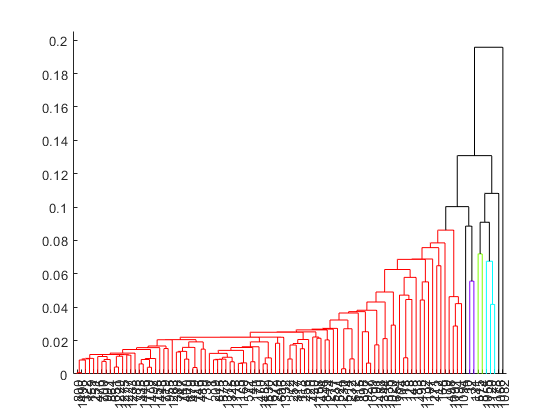

z = linkage(mappedX);
T = cluster(z,'maxclust',7);
cutoff = median(z(end-7:end-3,3));
figure,
[~,T2] = dendrogram(z,length(exemplar),'ColorThreshold',cutoff,'Labels',cellfun(@num2str,num2cell(exemplar),'un',0));
set(gca,'XTickLabelRotation',90);

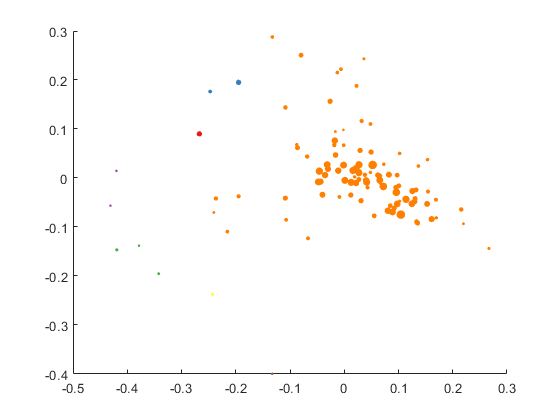

figure,scatter(mappedX(:,1),mappedX(:,2),sz_cluster,color(T,:),'filled');

C = unique(T);
final_exemplar = zeros(length(C),1);
figure,
[row,col] = arrange_subplots(length(C));
for i=1:length(C)
    idxtmp = find(T==i);
    boutdist_tmp = boutdist_microcluster(idxtmp,idxtmp);
    [~,I] = min(mean(boutdist_tmp,1));
    final_exemplar(i) = exemplar(idxtmp(I));
    subplot(row,col,i),
    plot_continuous_bouts(gca,bout_all_tmp{final_exemplar(i)});
end

let's try hierarchical clustering from the bottom directly

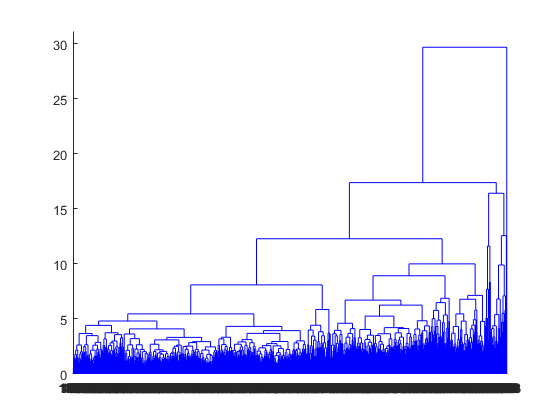

z = linkage(boutdist,'complete');
figure,
dendrogram(z,size(z,1));

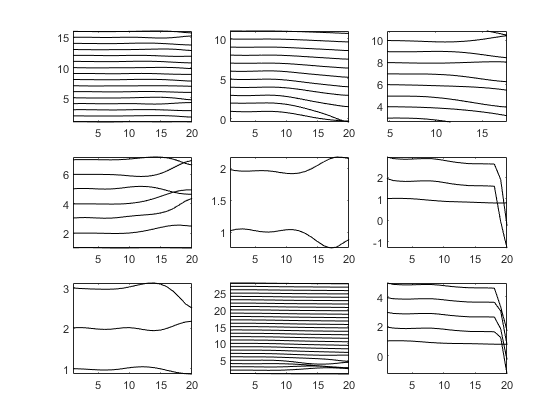

T = cluster(z,'maxclust',9);
C = unique(T);
final_exemplar = zeros(length(C),1);
sz_finalCluster = final_exemplar;
figure,
[row,col] = arrange_subplots(length(C));
for i=1:length(C)
    idxtmp = find(T==i);
    sz_finalCluster(i) = length(idxtmp);    
    boutdist_tmp = boutdist(idxtmp,idxtmp);
    [~,I] = min(mean(boutdist_tmp,1));
    final_exemplar(i) = idxtmp(I);
    subplot(row,col,i),
    plot_continuous_bouts(gca,bout_all_tmp{final_exemplar(i)});
end